Butterworth Filter Analysis:


   Filter order: 19


   Multiplications per input sample: 50
- - - - - - -


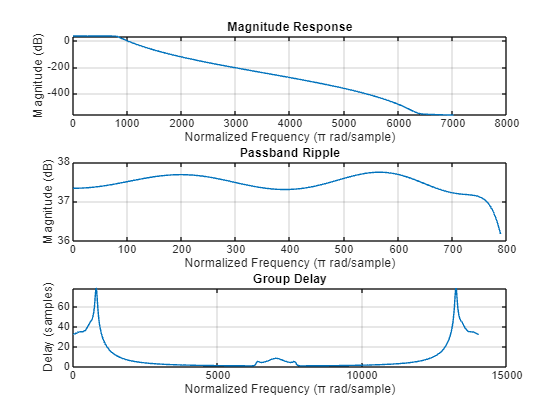

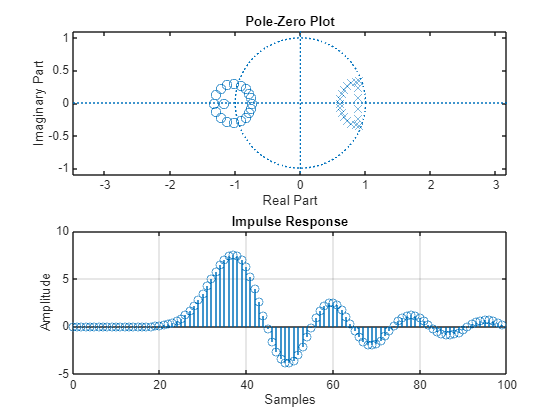

Chebyshev1 Filter Analysis:


   Filter order: 11


   Multiplications per input sample: 30
- - - - - - -


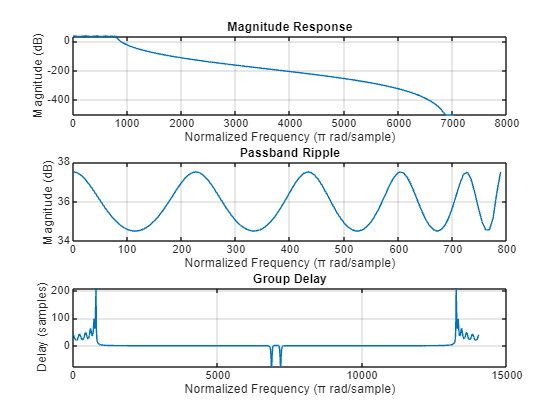

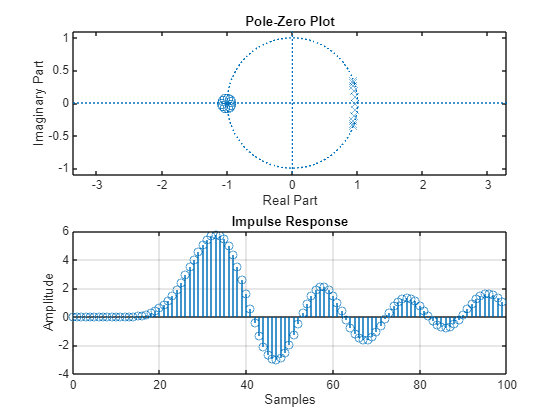

Chebyshev2 Filter Analysis:


   Filter order: 11


   Multiplications per input sample: 30
- - - - - - -


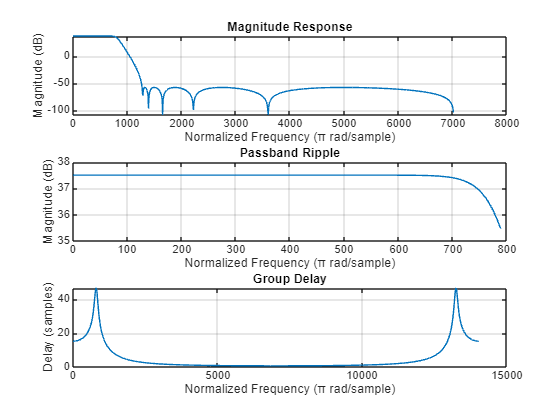

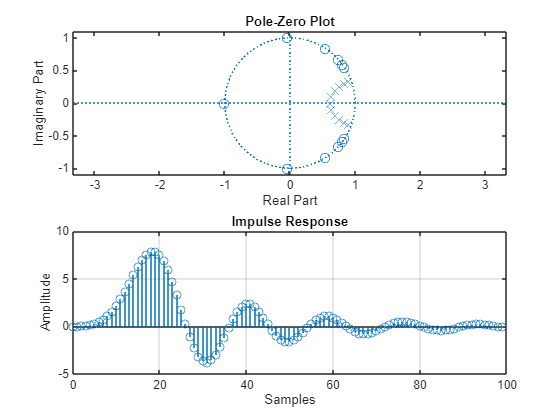

Elliptic Filter Analysis:


   Filter order: 8


   Multiplications per input sample: 20
- - - - - - -


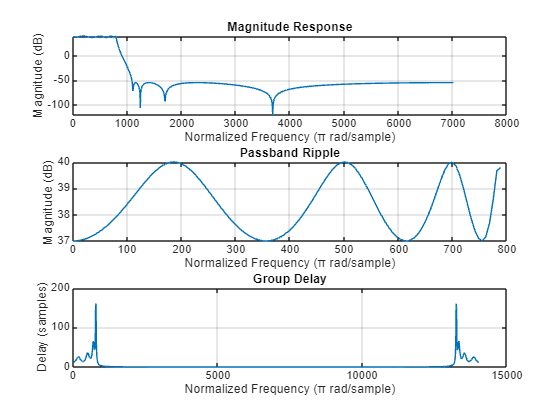

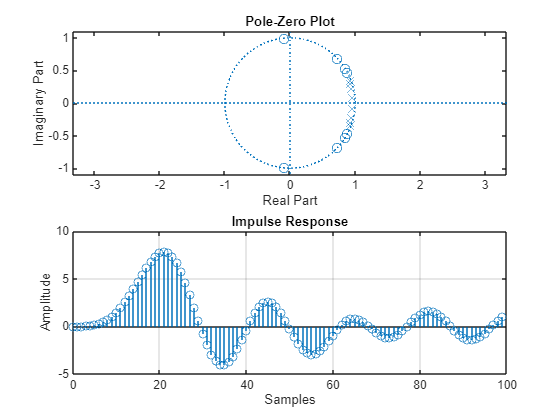

Parks-McClellan Filter Analysis:


   Filter order: 80


   Multiplications per input sample: 200
- - - - - - -


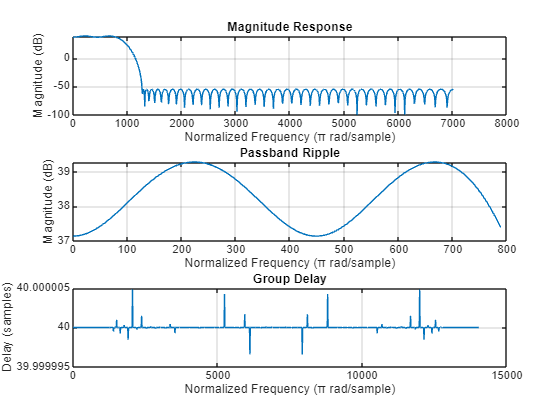

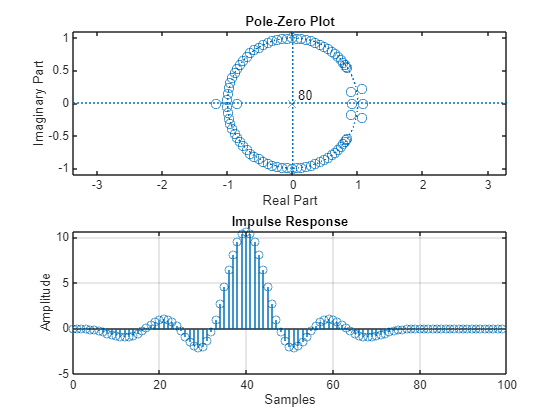

Kaiser Filter Analysis:


   Filter order: 138


   Multiplications per input sample: 345
- - - - - - -


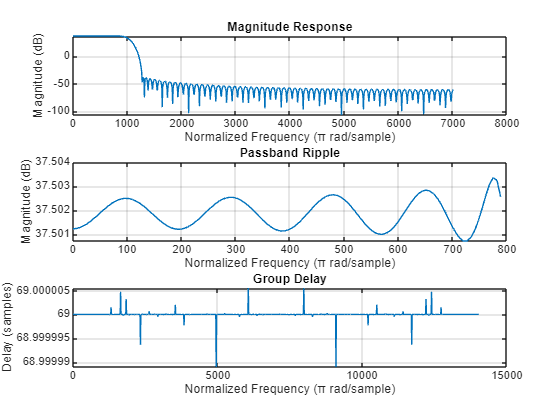

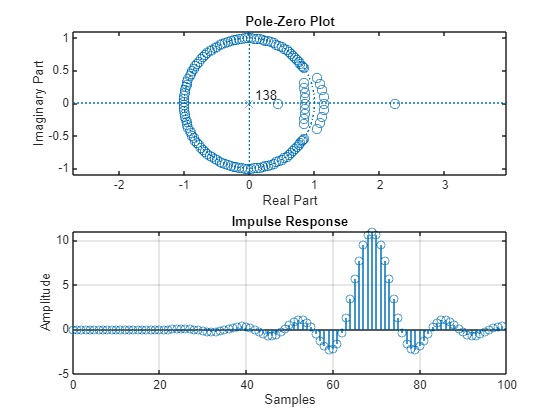

close all;
load projIB.mat % Load the noisy signal

% Define specifications
fs = 44100; % Sampling frequency
fp = 2500; % Passband frequency
fs_stop = 4000; % Stopband frequency
rp = 3; % Passband ripple (40-37 = 3 dB)
rs = 95; % Stopband attenuation in dB
gain = 75; % Gain at passband

% Normalize frequencies
nyq = fs/2;
wp = fp/nyq;
ws = fs_stop/nyq;

filter_types = {'Butterworth', 'Chebyshev1', 'Chebyshev2', 'Elliptic', 'Parks-McClellan', 'Kaiser'};
filtered_signals = zeros(180369, length(filter_types));

for i = 1:length(filter_types)
    fprintf('%s Filter Analysis:\n', filter_types{i});

    % Design filter based on type
    switch filter_types{i}
        case 'Butterworth'
        [n, wn] = buttord(wp, ws-500/nyq, rp, 55);
        [b, a] = butter(n, wn);
        sos = tf2sos(b*gain, a);

        case 'Chebyshev1'
        [n, wn] = cheb1ord(wp, ws, rp, rs);
        [b, a] = cheby1(n, rp, wn);
        sos = tf2sos(b*gain, a);
        
        case 'Chebyshev2'
        [n, wn] = cheb2ord(wp, ws, rp, rs);
        [b, a] = cheby2(n, rs, wn);
        sos = tf2sos(b*gain, a);

        case 'Elliptic'
        [n, wn] = ellipord(wp, ws, rp, rs);
        [b, a] = ellip(n, rp, rs, wn);
        sos = tf2sos(b*(gain+25), a);
        
        case 'Parks-McClellan'
        % Designed using filterDesigner
        Dpass = 0.10099735734;  
        Dstop = 1.77827941e-05;          
        dens = 20; 
        [n, Fo, Ao, W] = firpmord([fp, fs_stop]/(nyq), [1 0], [Dpass, Dstop]);

        b = firpm(n, Fo, Ao, W, {dens});
        a = 1;
        sos = tf2sos(b*(gain+7), a);
        
    case 'Kaiser'
        % Designed using filterDesigner
        Dpass = 0.17099735734;   
        Dstop = 1.77827941e-04;  
        [n, wn, beta, type] = kaiserord([fp fs_stop]/(nyq), [1 0], [Dstop Dpass]);

        b  = fir1(n, wn, type, kaiser(n+1, beta));
        a = 1; 
        sos = tf2sos(b*75, a);

    end

% Create filtered signal - store in column i of filtered_signals matrix
filtered_signals(:,i) = sosfilt(sos, noisy);

% (a) Filter order
fprintf('   Filter order: %d\n', n);

% (b) Number of multiplications per sample
% y[n] = b0*x[n] + b1*x[n-1] + b2*x[n-2] - a1*y[n-1] - a2*y[n-2]
mults = 5 * size(sos,1);
fprintf('   Multiplications per input sample: %d\n- - - - - - -\n', mults);

% (c) Plot magnitude response, passband detail, and group delay
figure('Name', sprintf('%s Filter Response', filter_types{i}));

% Magnitude response
[h, w] = freqz(sos, 1024, fs);
subplot(3,1,1);
plot(w/pi, 20*log10(abs(h)));
grid on;
title('Magnitude Response');
xlabel('Normalized Frequency (π rad/sample)');
ylabel('Magnitude (dB)');
    
% Passband ripple 
passband_idx = round(wp*1024);
subplot(3,1,2);
% Convert to dB and normalize to 0 dB
passband_response_db = 20*log10(abs(h(1:passband_idx)));
ripple = passband_response_db;
plot(w(1:passband_idx)/pi, ripple);
grid on;
title('Passband Ripple');
xlabel('Normalized Frequency (π rad/sample)');
ylabel('Magnitude (dB)');

% Group delay
[gd, w] = grpdelay(sos, 1024, 'whole', fs);
subplot(3,1,3);
plot(w/pi, gd);
grid on;
title('Group Delay');
xlabel('Normalized Frequency (π rad/sample)');
ylabel('Delay (samples)');
    
% (d) and (e) Pole-zero plot and impulse response
figure('Name', sprintf('%s Filter Characteristics', filter_types{i}));
    
% Pole-zero plot
subplot(2,1,1);
[z,p,~] = sos2zp(sos);
zplane(z,p);
title('Pole-Zero Plot');
    
% Impulse response
subplot(2,1,2);
imp = [1; zeros(99,1)];
imp_response = sosfilt(sos, imp);
stem(0:99, imp_response);
title('Impulse Response');
xlabel('Samples');
ylabel('Amplitude');
grid on;
end


fprintf('Currently Playing:\n');

Currently Playing:



filtered_signals(find(isnan(filtered_signals(:, 1))), 1) = 0;

for i = 1:length(filter_types)
    fprintf('  %s\n', filter_types{i});
    soundsc((i==1)*filtered_signals(:,i)+(i>1)*filtered_signals(:,i), fs);
    pause(length(noisy)/fs + 1);
end

  Butterworth
  Chebyshev1
  Chebyshev2
  Elliptic
  Parks-McClellan
  Kaiser
